% Change the current folder to the folder of this m-file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end

%% Defining parameters and file paths
% USER CONFIGURATION - Modify these settings for your dataset

% ========== FILE I/O PATHS ==========
% path to saving directory
ops.savedir = '../../outputs/test_data/Area2_1'; % Output folder for results and figures

% ========== ADD DEPENDENCIES TO PATH ==========
addpath('./Scripts/')                       % Core analysis scripts
addpath('./Scripts/bfmatlab/')              % Bio-Format Toolbox
addpath('./Scripts/MLspike/brick/')         % MLspike utilities
addpath('./Scripts/MLspike/spikes/')        % Spike detection functions
addpath('./Config/')                        % Configuration files  

% ========== LOAD DATA ==========
% ops.filename = fullfile(ops.savedir, 'denoised_im.tif');
% im_data = tiffreadVolume(ops.filename);

filename = fullfile(ops.savedir, 'processed_data.mat');
load(filename);

frame =2761;
n = 68;

if exist("h","var")
    clf(h)
end

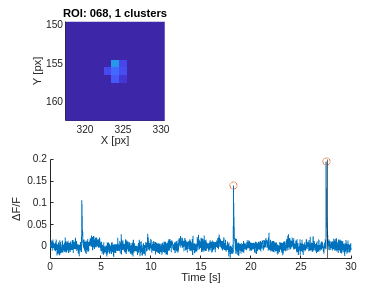

h = figure; 
n_row = 2;
n_col = 2;
ax_df_map = subplot(n_row, n_col, 1);
ax_trace = subplot(n_row, n_col, [3,4]);

n_cluster_ROI = sum(vertcat(event_cluster.ROI)==n);
[~,idx] = intersect(ind, ROI(n).PixelIdxList,'stable');

t = ROI(n).t;

% get location of each spike
[row,col] = ind2sub([ops.Ny, ops.Nx],ind(idx));
PixelList = [col,row];

xLim = [min(PixelList(:,1))-5, max(PixelList(:,1))+5];
yLim = [min(PixelList(:,2))-5, max(PixelList(:,2))+5];
x = xLim(1):xLim(2);
y = yLim(1):yLim(2);

df_map0 = zeros(yLim(2)-yLim(1)+1,xLim(2)-xLim(1)+1);
df_map = df_map0;
for i = 1:size(idx,1)
    x_loc = PixelList(i,1)-xLim(1)+1;
    y_loc = PixelList(i,2)-yLim(1)+1;
    df_map(y_loc, x_loc) =  signal_dfof(frame,idx(i));
end

axes(ax_df_map); %set the current axes
hold(ax_df_map,"on")
imagesc(ax_df_map, x, y, df_map)
xlim(ax_df_map, xLim)
ylim(ax_df_map, yLim)
set(ax_df_map, 'YDir','reverse')
title(ax_df_map, sprintf('ROI: %03d, %01d clusters', n, n_cluster_ROI))
xlabel(ax_df_map, 'X [px]')
ylabel(ax_df_map, 'Y [px]')
axis image

% plot traces
axes(ax_trace); %set the current axes
hold(ax_trace,"on")
clusters = find([event_cluster.ROI] == n);
for i = 1:length(clusters)
    c = clusters(i);
    plot(ax_trace, ops.t, event_cluster(c).dfof)
    scatter(ax_trace, ops.t(event_cluster(c).dff_t), event_cluster(c).dff)
end
xline(frame/ops.fs)
ylabel(ax_trace, '\DeltaF/F')
xlabel(ax_trace, 'Time [s]')

cLim = [0 max(event_cluster(c).dfof)*1.5];
clim(ax_df_map, cLim)